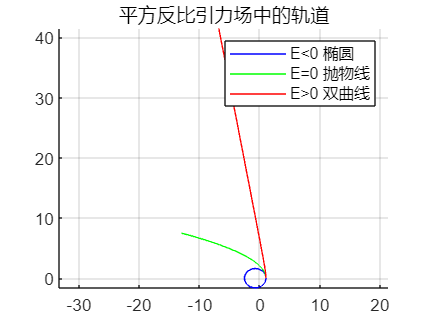

clear; clc; close all;

G = 1;      
m0 = 1; 
m = 1;

grav_ode = @(t,Y) gravity_equation(t,Y,G,m0);

figure; hold on; axis equal; grid on;
title('平方反比引力场中的轨道');

% (1) 椭圆 E<0
Y0 = [1; 0; 0; 1.2];
[t,Y] = ode45(grav_ode,[0 50],Y0);
plot(Y(:,1),Y(:,2),'b');

% (2) 抛物线 E=0
Y0 = [1; 0; 0; sqrt(2*G*m0/1)];
[t,Y] = ode45(grav_ode,[0 30],Y0);
plot(Y(:,1),Y(:,2),'g');

% (3) 双曲线 E>0
Y0 = [1; 0; 0; 2.5];
[t,Y] = ode45(grav_ode,[0 20],Y0);
plot(Y(:,1),Y(:,2),'r');

legend('E<0 椭圆','E=0 抛物线','E>0 双曲线');

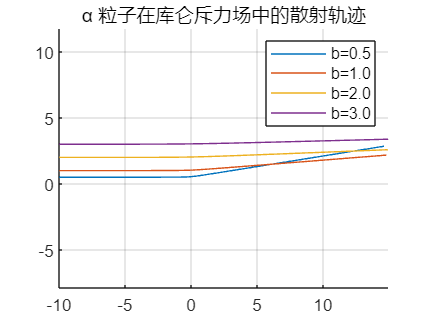

clear; clc; close all;

k = 1;      
m = 1;

rep_ode = @(t,Y) repulsion_equation(t,Y,k,m);

figure; hold on; axis equal; grid on;
title('α 粒子在库仑斥力场中的散射轨迹');

v0 = 5;       
x0 = -10;     

for b = [0.5 1.0 2.0 3.0]   % 冲量参数
    Y0 = [x0; b; v0; 0];
    [t,Y] = ode45(rep_ode,[0 5],Y0);
    plot(Y(:,1),Y(:,2));
end

legend('b=0.5','b=1.0','b=2.0','b=3.0');


% 库仑斥力动力学方程

function dY = repulsion_equation(t,Y,k,m)
    x = Y(1); y = Y(2);
    vx = Y(3); vy = Y(4);
    r = sqrt(x^2 + y^2);
    ax = k*x/(m*r^3);
    ay = k*y/(m*r^3);
    dY = [vx; vy; ax; ay];
end

% 下面是动力学方程函数
function dY = gravity_equation(t,Y,G,m0)
    x = Y(1); y = Y(2);
    vx = Y(3); vy = Y(4);
    r = sqrt(x^2 + y^2);
    ax = -G*m0*x/(r^3);
    ay = -G*m0*y/(r^3);
    dY = [vx; vy; ax; ay];
end